## Lectura de datos

El imageDatastore permite manipular datos a gran escala, sin necesidad de cargar todas las imagenes a la vez.

dsModels = imageDatastore("Models\Meta\*.png");
ds = imageDatastore(["Train1\Train1\", "Train2\Train2\"], "LabelSource","foldernames", "IncludeSubfolders",true);
nFiles = numel(ds.Files)

nFiles = 39209

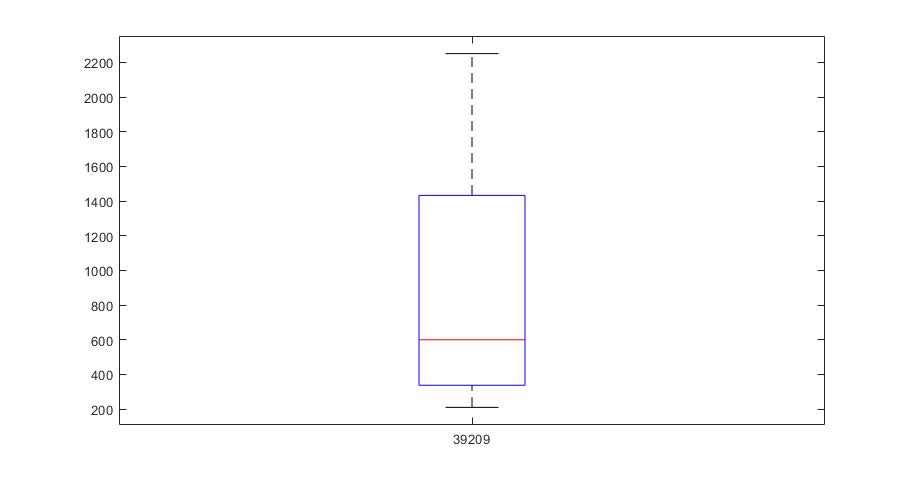

%podemos mirar cuantos items de cada clase hay y la distribución:
eachLable = countEachLabel(ds);
boxplot(eachLable.Count, nFiles);


%De la misma manera, aplicar un ordenado aleatorio tambien es comun en los
%preparativos para entrenar un modelo:
ds = shuffle(ds);

Es interesante que de cada clase hayan aproximadamente la misma cantidad de representantes, de otra manera el modelo puede estar desviado. (Esto mas adelante).

## Split Dataset

Ahora generaremos una particion en el datastore, un 80% sera para entrenar el modelo y el restante para test.

[train,test] = splitEachLabel(ds,0.8);
nTrain = numel(train.Files)

nTrain = 31367

nTest = numel(test.Files)

nTest = 7842

%[train,test] = splitEachLabel(dsTrain,0.8,'randomized');
% tmb se puede hacer con : subset

## Calcular Caracteristicas

Ahora hay que construir la tabla con los estadisticos que usaremos para entrenar el modelo.

Tenemos una funcion que recibe una image, la filtra y calcula los estadisticos.

Generaremos una tabla con la etiqueta de cada foto y sus datos estadisticos.

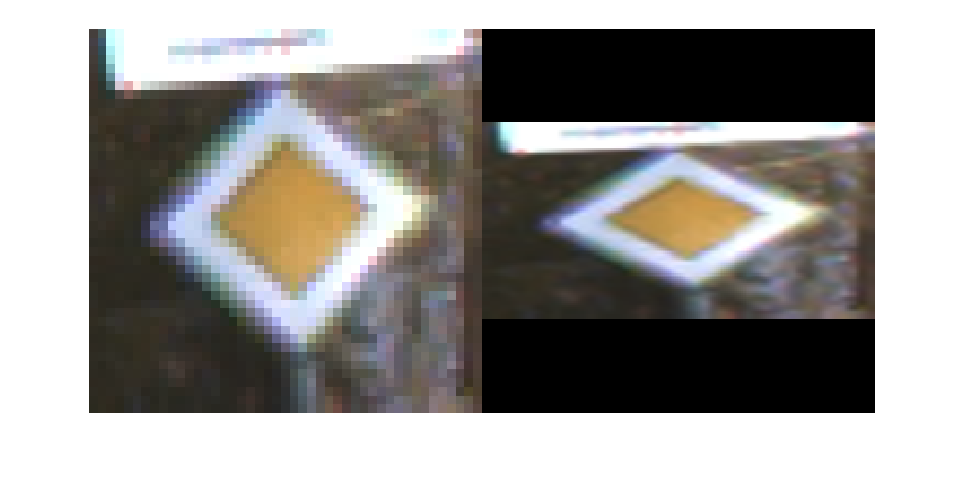

targetSize = [100,200]; %funcion de ejemplo, de momento.
trainTransform = transform(train, @(x) imresize(x,targetSize));
montage({read(train), read(trainTransform)});